clear
clc

%weight distribution array
weight=[418.9,  1.6;    %avionics
        23.9,   2.17;   %nose landing gear
        52.9,   2.9;    %instruments
        187.7,  4.95;   %furnishings
        420,    6;      %payload
        9.3,    6.5;    %anti icing
        190.34, 6.57;   %flight controls
        57.8,   7.25;   %main landing gear
        38.7,   7.49;   %fuel system
        319.5,  7.71;   %Wing
        70.1,   8.22;   %air conditioning
        1.4,    8.22;   %handling gear
        29.3,   8.22;   %hydraulics
        205.3,  8.68;   %electrical system
        26.5,   8.68;   %engine control
        418,    9.65;   %engine x2
        21.25,  9.65;   %engine starter
        136.3,  9.65;   %nacelle   
        36,     10.57;  %vertical tailplane
        50.3,   10.89]  %horizontal tailplane    

weight =   418.9000    1.6000
   23.9000    2.1700
   52.9000    2.9000
  187.7000    4.9500
  420.0000    6.0000
    9.3000    6.5000
  190.3400    6.5700
   57.8000    7.2500
   38.7000    7.4900
  319.5000    7.7100


         
fusweight=686.1/12; %per unit length
cg=6.665;

%setting front and rear spar locations
fsparlocation=7.0539;
aftsparlocation=8.2689;
Uclocation=7.25;

enginey=1.2

enginey = 1.2000

enginez=0.35

enginez = 0.3500


ac=7.8994;
achtailx=11.5; %provvisorio
acvtailz=1.955 

acvtailz = 1.9550

acvtailx=11.309

acvtailx = 11.3090

**Symmetric flight at the ultimate load factor**

%load factors
n1=2.5*1.5;
n2=-1*1.5;

%creating the two loading conditions
force1=weight(:,1)*9.81*n1; 
force2=weight(:,1)*9.81*n2;

%calculating reaction forces for n1
syms Rf Rr

f1 = Rf + Rr + sum(force1) + fusweight*12*(n1) == 0;
f2 = Rf*fsparlocation + Rr*aftsparlocation + sum(force1.*weight(:,2)) + fusweight*12*6*(n1) == 0;

[A,B] = equationsToMatrix([f1, f2], [Rf, Rr]);

X = linsolve(A,B);

Rf1=double(X(1))

Rf1 = -1.3520e+05

Rr1=double(X(2))

Rr1 = 3.2808e+04


%calculating reaction forces for n2
syms Rf Rr

f1 = Rf + Rr + sum(force2) + fusweight*12*(n2) == 0;
f2 = Rf*fsparlocation + Rr*aftsparlocation + sum(force2.*weight(:,2)) + fusweight*12*6*(n2) == 0;

[A,B] = equationsToMatrix([f1, f2], [Rf, Rr]);

X = linsolve(A,B);

Rf2=double(X(1))

Rf2 = 5.4082e+04

Rr2=double(X(2))

Rr2 = -1.3123e+04

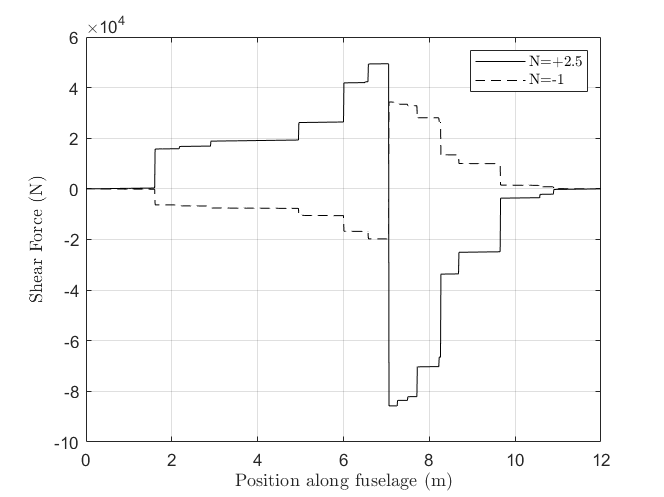


%creating point load arrays
load1(:,1)=[weight(1:7,2);fsparlocation;weight(8:13,2);aftsparlocation;weight(14:20,2)];
load1(:,2)=[force1(1:7);Rf1;force1(8:13);Rr1;force1(14:20)];

load2(:,1)=[weight(1:7,2);fsparlocation;weight(8:13,2);aftsparlocation;weight(14:20,2)];
load2(:,2)=[force2(1:7);Rf2;force2(8:13);Rr2;force2(14:20)];

%determining shear force for n=2.5
sforce1(:,1)=linspace(0,12,1201);

for n=0:1200
    sforce1(n+1,2)=sum(load1(load1(:,1)<(n/100),2))+fusweight*(n/100)*n1;
end

%determining shear force for n=-1
sforce2(:,1)=linspace(0,12,1201);

for n=0:1200
    sforce2(n+1,2)=sum(load2(load2(:,1)<(n/100),2))+fusweight*(n/100)*n2;
end

%plotting shear force
a=figure;
set(gca,'TickLabelInterpreter','latex')
plot(sforce1(:,1),sforce1(:,2),'-k')
hold on
grid on
plot(sforce2(:,1),sforce2(:,2),'--k')
legend('N=+2.5','N=-1','interpreter','latex')
xlabel('Position along fuselage (m)','interpreter','latex')
ylabel('Shear Force (N)','interpreter','latex')
ylim([-100000,60000])
saveas(a,'sf1.png')

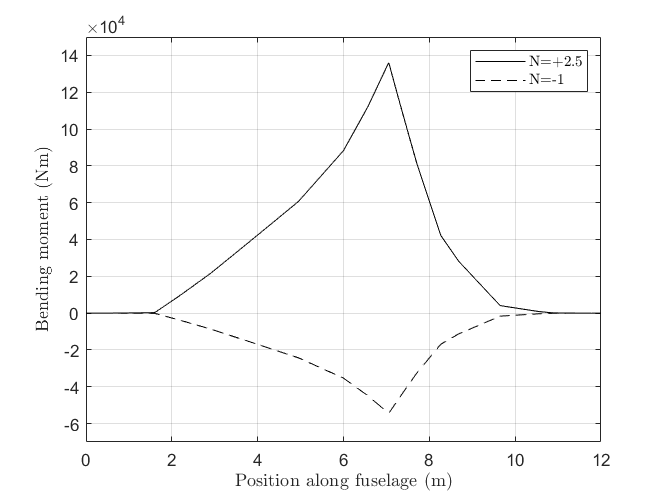


%determining bending moment for n=2.5
bmoment1(:,1)=linspace(0,12,1201);

for n=0:1200
    bmoment1(n+1,2)=sum(load1(load1(:,1)<(n/100),2).*(n/100-load1(load1(:,1)<(n/100),1)))+fusweight*(n/100)*(n/200)*n1;
end

%determining bending moment for n=-1
bmoment2(:,1)=linspace(0,12,1201);

for n=0:1200
    bmoment2(n+1,2)=sum(load2(load2(:,1)<(n/100),2).*(n/100-load2(load2(:,1)<(n/100),1)))+fusweight*(n/100)*(n/200)*n2;
end

%plotting bending moment
b=figure;
set(gca,'TickLabelInterpreter','latex')
plot(bmoment1(:,1),bmoment1(:,2),'-k')
hold on
grid on
plot(bmoment2(:,1),bmoment2(:,2),'--k')
legend('N=+2.5','N=-1','interpreter','latex')
xlabel('Position along fuselage (m)','interpreter','latex')
ylabel('Bending moment (Nm)','interpreter','latex')
ylim([-70000,150000])
saveas(b,'bm1.png')

**Landing with front nose-off case**

temp=weight;
fuelweight(:,1)=[weight(1:10,1);1300.4;weight(11:end,1)];
fuelweight(:,2)=[weight(1:10,2);8.11;weight(11:end,2)];
weight=fuelweight;

%load factor
n3=1*1.5;

%supported by undercarriage
%creating n=1 loading condition
force3=weight(:,1)*9.81*n3;

%calculating reaction forces for n3
syms Uc Tail

f1 = Uc + sum(force3) + fusweight*12*n3 + Tail == 0;
f2 = Uc*Uclocation + Tail*achtailx + sum(force3.*weight(:,2)) + fusweight*12*6*n3 == 0;

[A,B] = equationsToMatrix([f1, f2], [Uc, Tail]);

X = linsolve(A,B);

Uc=double(X(1))

Uc = -6.1863e+04

Tail=double(X(2))

Tail = 1.7695e+03

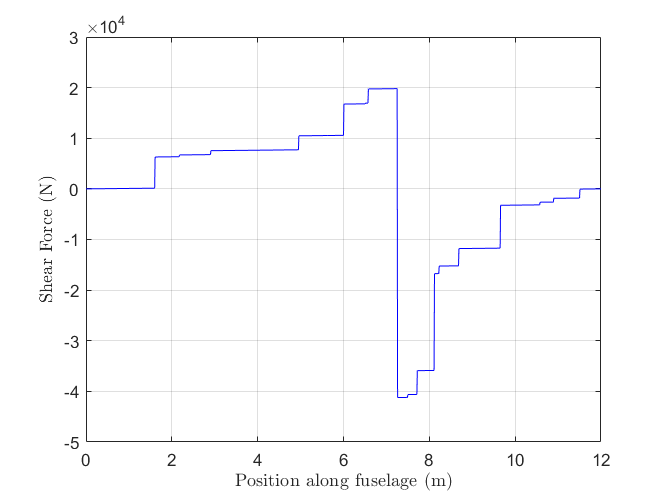


%creating point load array
load3(:,1)=[weight(1:7,2);Uclocation;weight(8:21,2);achtailx];
load3(:,2)=[force3(1:7);Uc;force3(8:21);Tail];

%calculating shear force
sforce3(:,1)=linspace(0,12,1201);

for n=0:1200
    sforce3(n+1,2)=sum(load3(load3(:,1)<(n/100),2))+fusweight*(n/100)*n3;
end

%plotting shear force
c=figure;
set(gca,'TickLabelInterpreter','latex')
plot(sforce3(:,1),sforce3(:,2),'-b')
grid on
xlabel('Position along fuselage (m)','interpreter','latex')
ylabel('Shear Force (N)','interpreter','latex')
ylim([-50000,30000])
saveas(c,'sf3.png')

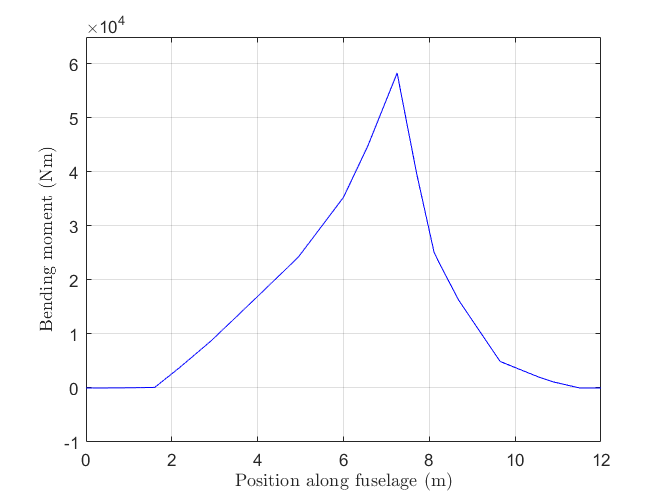


%determining bending moment for n=1
bmoment3(:,1)=linspace(0,12,1201);

for n=0:1200
    bmoment3(n+1,2)=sum(load3(load3(:,1)<(n/100),2).*(n/100-load3(load3(:,1)<(n/100),1)))+fusweight*(n/100)*(n/200)*n3;
end

%plotting bending moment
d=figure;
set(gca,'TickLabelInterpreter','latex')
plot(bmoment3(:,1),bmoment3(:,2),'-b')
grid on
xlabel('Position along fuselage (m)','interpreter','latex')
ylabel('Bending moment (Nm)','interpreter','latex')
ylim([-10000,65000])
saveas(d,'bm3.png')

**One engine inoperative**

Torque

%creating the loading conditions
engineztorque=9340*enginey

engineztorque = 11208

engineytorque=9340*enginez

engineytorque = 3269


elevatorforce=engineztorque/(acvtailx-cg)

elevatorforce = 2.4134e+03

htailforce=engineytorque/(achtailx-cg)

htailforce = 676.1117

elevatorxtorque=elevatorforce*acvtailz

elevatorxtorque = 4.7183e+03

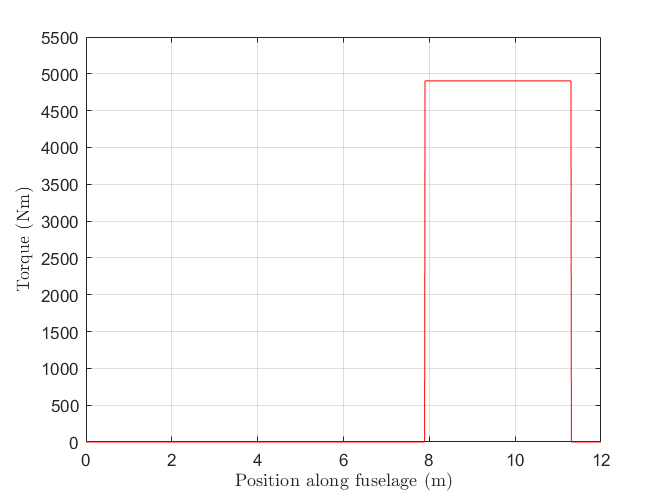


%calculating torque distribution
moment(:,1)=[ac;acvtailx];
moment(:,2)=[engineytorque;-engineytorque]*1.5;

%calculating torque
torque(:,1)=linspace(0,12,1201);

for n=0:1200
    torque(n+1,2)=sum(moment(moment(:,1)<(n/100),2));
end

%plotting torque
e=figure;
set(gca,'TickLabelInterpreter','latex')
plot(torque(:,1),torque(:,2),'-r')
grid on
xlabel('Position along fuselage (m)','interpreter','latex')
ylabel('Torque (Nm)','interpreter','latex')
ylim([0,5500])
saveas(e,'t2.png')

Shear force and bending moment 

weight=temp

weight =   418.9000    1.6000
   23.9000    2.1700
   52.9000    2.9000
  187.7000    4.9500
  420.0000    6.0000
    9.3000    6.5000
  190.3400    6.5700
   57.8000    7.2500
   38.7000    7.4900
  319.5000    7.7100



%load factor
n4=1*1.5;

%creating the two loading conditions
force4(:,1)=[weight(:,2);achtailx]; %provvisorio
force4(:,2)=[weight(:,1)*9.81;htailforce]*n4; %provvisorio

%calculating reaction forces for n1
syms Rf Rr

f1 = Rf + Rr + sum(force4(:,2)) + fusweight*12*n4 == 0;
f2 = Rf*fsparlocation + Rr*aftsparlocation + sum(force4(:,2).*force4(:,1)) + fusweight*12*6*n4 == 0;

[A,B] = equationsToMatrix([f1, f2], [Rf, Rr]);

X = linsolve(A,B);

Rf1=double(X(1))

Rf1 = -5.1385e+04

Rr1=double(X(2))

Rr1 = 9.4122e+03


%creating point load arrays
load4(:,1)=[force4(1:7,1);fsparlocation;force4(8:13,1);aftsparlocation;force4(14:21,1)]; %provvisorio
load4(:,2)=[force4(1:7,2);Rf1;force4(8:13,2);Rr1;force4(14:21,2)]; %provvisorio

fsparlocation

fsparlocation = 7.0539

aftsparlocation

aftsparlocation = 8.2689

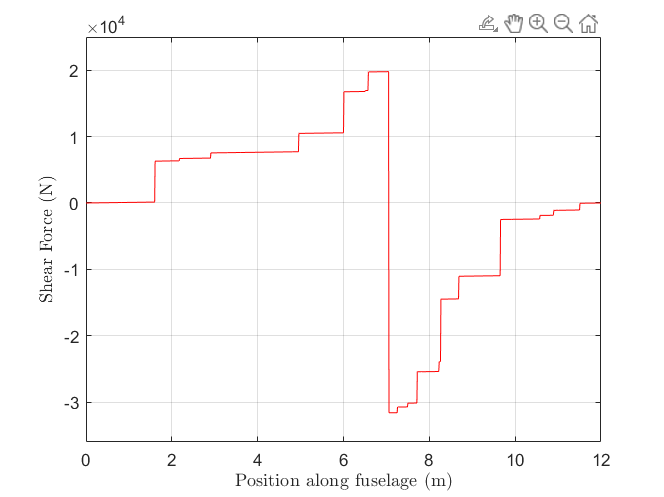


%determining shear force
sforce4(:,1)=linspace(0,12,1201);

for n=0:1200
    sforce4(n+1,2)=sum(load4(load4(:,1)<(n/100),2))+fusweight*(n/100)*n4;
end

%plotting shear force
f=figure;
set(gca,'TickLabelInterpreter','latex')
plot(sforce4(:,1),sforce4(:,2),'-r')
grid on
xlabel('Position along fuselage (m)','interpreter','latex')
ylabel('Shear Force (N)','interpreter','latex')
xlim([0,12])
ylim([-36000,25000])

saveas(f,'sf2.png')

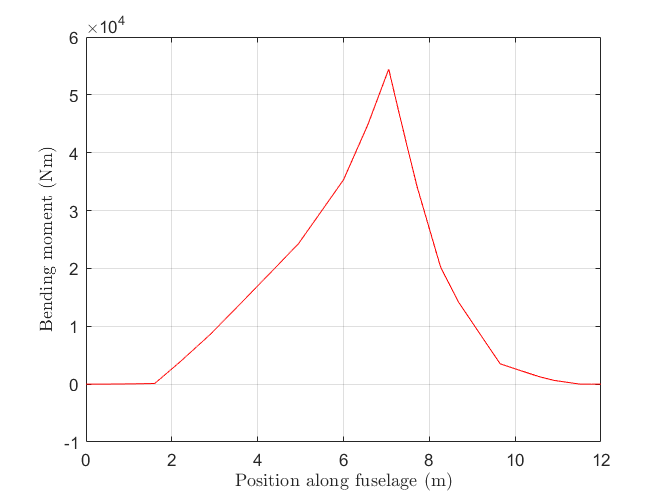


%determining bending moment for n=-1
bmoment4(:,1)=linspace(0,12,1201);

for n=0:1200
    bmoment4(n+1,2)=sum(load4(load4(:,1)<(n/100),2).*(n/100-load4(load4(:,1)<(n/100),1)))+fusweight*(n/100)*(n/200)*n4;
end

%plotting bending moment
g=figure;
set(gca,'TickLabelInterpreter','latex')
plot(bmoment4(:,1),bmoment4(:,2),'-r')
grid on
xlabel('Position along fuselage (m)','interpreter','latex')
ylabel('Bending moment (Nm)','interpreter','latex')
saveas(g,'bm2.png')

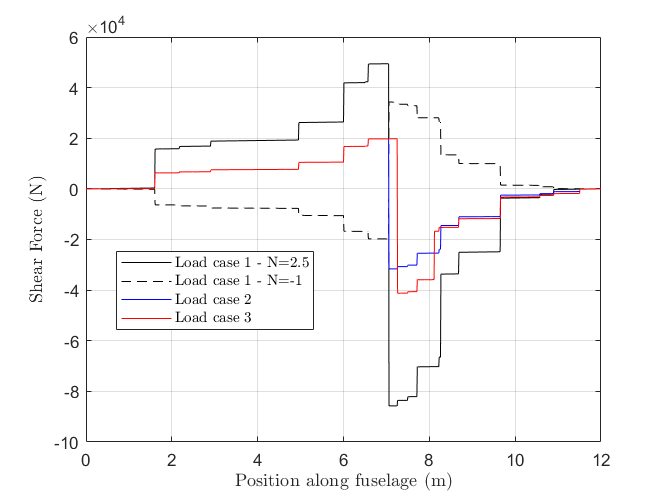

%final plots
h=figure;
set(gca,'TickLabelInterpreter','latex')
plot(sforce1(:,1),sforce1(:,2),'k')
hold on
grid on
plot(sforce2(:,1),sforce2(:,2),'--k')
plot(sforce4(:,1),sforce4(:,2),'b')
plot(sforce3(:,1),sforce3(:,2),'r')
legend('Load case 1 - N=2.5','Load case 1 - N=-1','Load case 2','Load case 3','Location','best','interpreter','latex')
xlabel('Position along fuselage (m)','interpreter','latex')
ylabel('Shear Force (N)','interpreter','latex')
ylim([-100000,60000])
saveas(h,'sftot.png')

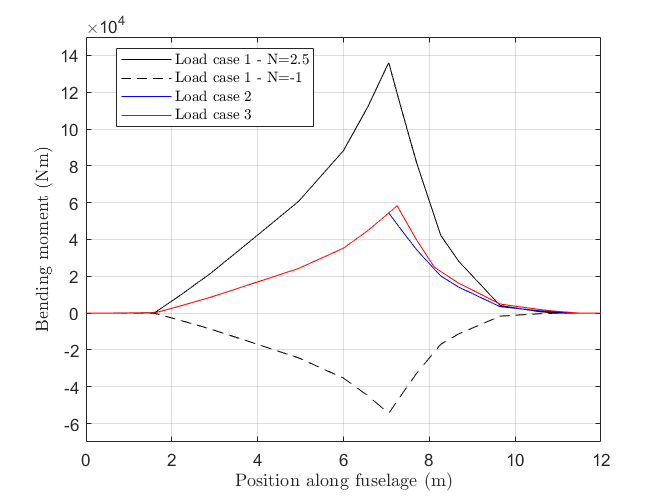


i=figure;
set(gca,'TickLabelInterpreter','latex')
plot(bmoment1(:,1),bmoment1(:,2),'k')
hold on
grid on
plot(bmoment2(:,1),bmoment2(:,2),'--k')
plot(bmoment4(:,1),bmoment4(:,2),'b')
plot(bmoment3(:,1),bmoment3(:,2),'r')
legend('Load case 1 - N=2.5','Load case 1 - N=-1','Load case 2','Load case 3','Location','best','interpreter','latex')
xlabel('Position along fuselage (m)','interpreter','latex')
ylabel('Bending moment (Nm)','interpreter','latex')
ylim([-70000,150000])
saveas(i,'bmtot.png')